## A03 - MMcK

clear all;
close all;
clc;

Consider a system modelled with an *M/M/c/K* queue, with $K=10$ and the service demand reported below. Consider the system under different workloads according to the minimum and maximum values reported below. In particular, consider 51 equally spaced arrival rates between the two values. Consider also different configurations, varying the number of servers from $c=1$ to $c=8$.


$$D = 2\\
\lambda_{min} = 1\\
\lambda_{max} = 10\\
R_{th} = 3$$


where $R_{th}$ is the response time threshold.

D = 2;
Lmin = 1;
Lmax = 10;
Rth = 3;

Let's compute the 51 intervals for $\lambda$:

L = (Lmin:(Lmax-Lmin)/50:Lmax)

L =     1.0000    1.1800    1.3600    1.5400    1.7200    1.9000    2.0800    2.2600    2.4400    2.6200    2.8000    2.9800    3.1600    3.3400    3.5200    3.7000    3.8800    4.0600    4.2400    4.4200    4.6000    4.7800    4.9600    5.1400    5.3200    5.5000    5.6800    5.8600    6.0400    6.2200    6.4000    6.5800    6.7600    6.9400    7.1200    7.3000    7.4800    7.6600    7.8400    8.0200    8.2000    8.3800    8.5600    8.7400    8.9200    9.1000    9.2800    9.4600    9.6400    9.8200


c = (1:8)

c =      1     2     3     4     5     6     7     8


K = 10

K = 10

In *MMcK *the formulas used to compute the several metrics are quite ugly. So the idea is to compute first $p_i$, so the probability that in the system there are $i$ jobs, and then all the other metrics.

First of all, let's compute $p_0$ from:


$$p_0 = \left[ \frac{(c\rho)^c}{c!} \frac{1-\rho^{K-c+1}}{1-\rho} + \sum_{k=0}^{c-1} \frac{(c\rho)^k}{k!} \right]^{-1}$$


p0 = @(C, p, k, K) ( (C*p)^C/factorial(C) * (1-p^(K-C+1))/(1-p) + sum(((C*p).^k)./factorial(k)) )^-1;

P0 = zeros(length(L), length(c));

for i = 1:length(L)
    for j = 1:length(c)
        rho = L(i)*D/c(j);
        k = 0:c(j)-1;
        
        P0(i,j) = p0(c(j), rho, k, K);
    end
end

P0T = array2table(P0, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

P0T = 51×8 table
                1             2             3             4             5             6             7             8     
            __________    __________    __________    __________    __________    __________    __________    __________

    1       0.00048852           NaN       0.11307       0.13061       0.13436       0.13515        0.1353       0.13533
    1.18    0.00010753      0.017696       0.06708      0.087646      0.092845      0.094074      0.094353      0.094411
    1.36    2.8528e-05     0.0063696      0.037113      0.057402      0.063678      0.065344      0.065762       0.06586
    1.54    8.7904e-06     0.0023628 

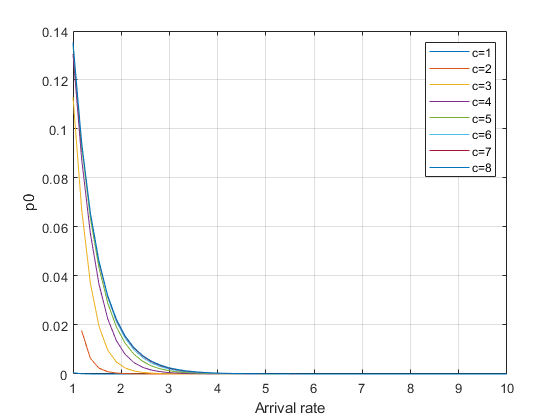

plot(L, P0, "-");
legend(["c=1", "c=2", "c=3", "c=4", "c=5", "c=6", "c=7", "c=8"]);
xlabel("Arrival rate");
ylabel("p0");
grid on;
hold off;

As we can see the probability that in the system there are no jobs:

- decreases as the arrival rate $\lambda$ increases

- increases as the number of servers $c$ increases

Let's now compute $p_n$


$$p_n = 
\begin{cases}
  \frac{p_0}{n!} \cdot (c\rho)^n & & n < c\\
  \frac{p_0 \cdot c^c \cdot \rho^n}{c!} & & c \leq n \leq K
\end{cases}$$


Note that here we will have a tridimensional structure since we will have a $p_n$ for each value of $\lambda, c$ and $n$

pn1 = @(p0, n, c, p) p0/factorial(n) * (c*p)^n;
pn2 = @(p0, n, c, p) (p0 * c^c * p^n) / factorial(c);

Pn = zeros(length(L), length(c), K+1);

for i = 1:length(L)
    for j = 1:length(c)
        for n = 0:K
            rho = L(i)*D/c(j);
            
            if n == 0
                Pn(i,j,n+1) = P0(i,j);
            elseif n < c(j)
                Pn(i,j,n+1) = pn1(P0(i,j), n, c(j), rho);
            else
                Pn(i,j,n+1) = pn2(P0(i,j), n, c(j), rho);
            end            
        end
    end
end

Pn

Pn = Pn(:,:,1) =

    0.0005       NaN    0.1131    0.1306    0.1344    0.1351    0.1353    0.1353
    0.0001    0.0177    0.0671    0.0876    0.0928    0.0941    0.0944    0.0944
    0.0000    0.0064    0.0371    0.0574    0.0637    0.0653    0.0658    0.0659
    0.0000    0.0024    0.0194    0.0365    0.0432    0.0452    0.0458    0.0459
    0.0000    0.0009    0.0098    0.0226    0.0290    0.0312    0.0319    0.0320
    0.0000    0.0004    0.0049    0.0136    0.0192    0.0214    0.0221    0.0224
    0.0000    0.0002    0.0025    0.0080    0.0126    0.0146    0.0154    0.0156
    0.0000    0.0001    0.0013    0.0047    0.0081    0.0099    0.0106    0.0109
    0.0000    0.0000    0.0007    0.0028    0.0052    0.0067    0.0074    0.0076
    0.0000    0.0000    0.0004    0.0016    0.0034    0.0045    0.0051    0.0053
    0.0000    0.0000    0.0002    0.0010    0.0022    0.0031    0.0035    0.0037
    0.0000    0.0000    0.0001    0.0006    0.0014    0.0021    0.0025    0.0026
    0.0000

### b. Compute N


$$N = \sum_{i=1}^{K} i \cdot p_i$$


n_fun = @(Pn, l, c, k) k*squeeze(Pn(l,c,k+1));

N = zeros(length(L), length(c));

k = 1:K;
for i = 1:length(L)
    for j = 1:length(c)
        N(i,j) = n_fun(Pn, i, j, k);
    end
end

NT = array2table(N, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

NT = 51×8 table
              1         2         3         4         5         6         7         8   
            ______    ______    ______    ______    ______    ______    ______    ______

    1       9.0054       NaN    2.7105    2.1605    2.0374    2.0083    2.0016    2.0002
    1.18    9.2656    6.6859    3.6547    2.6883    2.4446    2.3809    2.3645    2.3606
    1.36    9.4188    7.6575    4.7168    3.3032    2.8842     2.764    2.7302    2.7213
    1.54    9.5193    8.2637    5.7468    3.9967    3.3619     3.161    3.0996    3.0821
    1.72    9.5902    8.6474    6.6246    4.7333    3.8764    3.5733    3.4732    3.4426
   

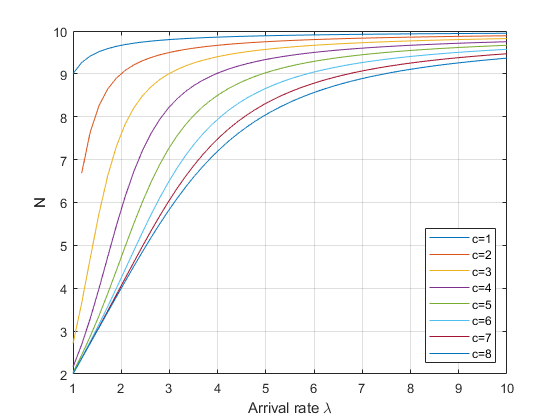

plot(L, N, "-");
legend(["c=1", "c=2", "c=3", "c=4", "c=5", "c=6", "c=7", "c=8"], 'Location', 'southeast');
xlabel("Arrival rate \lambda");
ylabel("N");
grid on;
hold off;

### c. Compute U


$$U = \sum_{i=1}^c i \cdot p_i + c \cdot \sum_{i=c+1}^K p_i$$


u_fun = @(Pn, l, c, K) ((1:c)*squeeze(Pn(l,c,2:c+1)) + c*sum(Pn(l,c,c+2:K+1))) / c;

U = zeros(length(L), length(c));

for i = 1:length(L)
    for j = 1:length(c)
        U(i,j) = u_fun(Pn, i, j, K);
    end
end

UT = array2table(U, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

UT = 51×8 table
               1          2          3          4          5          6          7          8   
            _______    _______    _______    _______    _______    _______    _______    _______

    1       0.99951        NaN    0.66078    0.49932    0.39985    0.33328    0.28569    0.24999
    1.18    0.99989    0.96142    0.76511    0.58718    0.47137    0.39312    0.33704    0.29494
    1.36    0.99997    0.98497    0.84983     0.6712    0.54195    0.45263    0.38824    0.33981
    1.54    0.99999      0.994    0.91022    0.74802    0.61054    0.51142     0.4391    0.38447
    1.72          1    0.99748    0.94856   

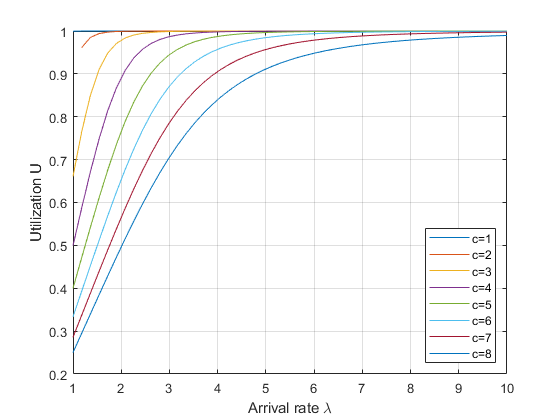

plot(L, U, "-");
legend(["c=1", "c=2", "c=3", "c=4", "c=5", "c=6", "c=7", "c=8"], 'Location', 'southeast');
xlabel("Arrival rate \lambda");
ylabel("Utilization U");
grid on;
hold off;

### d. Compute X

###  
$$X = \lambda \cdot (1-p_K)$$


x_fun = @(lambda, pk) lambda*(1-pk);

X = zeros(length(L), length(c));

for i = 1:length(L)
    for j = 1:length(c)
        X(i,j) = x_fun(L(i), Pn(i,j,K+1));
    end
end

XT = array2table(X, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

XT = 51×8 table
               1          2          3          4          5          6          7          8   
            _______    _______    _______    _______    _______    _______    _______    _______

    1       0.49976        NaN    0.99118    0.99864    0.99963    0.99985    0.99992    0.99995
    1.18    0.49995    0.96142     1.1477     1.1744     1.1784     1.1794     1.1797     1.1798
    1.36    0.49999    0.98497     1.2747     1.3424     1.3549     1.3579     1.3589     1.3592
    1.54        0.5      0.994     1.3653      1.496     1.5264     1.5343     1.5369     1.5379
    1.72        0.5    0.99748     1.4228   

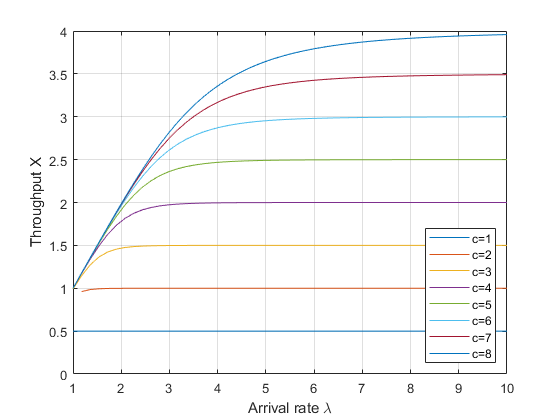

plot(L, X, "-");
legend(["c=1", "c=2", "c=3", "c=4", "c=5", "c=6", "c=7", "c=8"], 'Location', 'southeast');
xlabel("Arrival rate \lambda");
ylabel("Throughput X");
grid on;
hold off;

We can see that where the throughput becames constant, it is equal to $1/D_{max}$

### e. Compute R

Compute R by Little's Law


$$R = \frac{N}{X}$$


R = N ./ X;

RT = array2table(R, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

RT = 51×8 table
              1         2         3         4         5         6         7         8   
            ______    ______    ______    ______    ______    ______    ______    ______

    1        18.02       NaN    2.7346    2.1635    2.0382    2.0086    2.0018    2.0003
    1.18    18.533    6.9542    3.1844    2.2892    2.0744    2.0188    2.0044    2.0009
    1.36    18.838    7.7743    3.7002    2.4607    2.1287    2.0355    2.0092    2.0021
    1.54    19.039    8.3136    4.2091    2.6715    2.2025    2.0603    2.0168    2.0041
    1.72     19.18    8.6693    4.6559    2.9067    2.2949    2.0938     2.028    2.0073
   

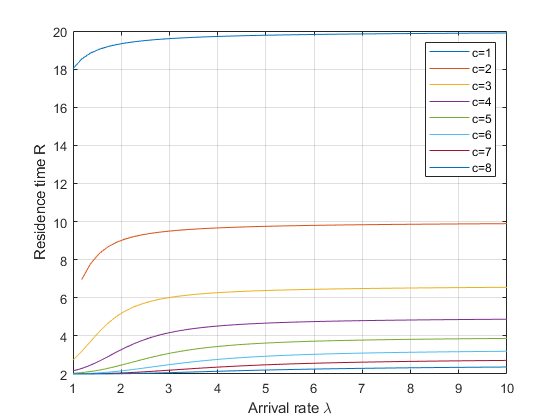

plot(L, R, "-");
legend(["c=1", "c=2", "c=3", "c=4", "c=5", "c=6", "c=7", "c=8"], 'Location', 'northeast');
xlabel("Arrival rate \lambda");
ylabel("Residence time R");
grid on;
hold off;

### f. Compute $\Theta$


$$\Theta = R - D$$


Theta = R - D;

ThetaT = array2table(Theta, ...
    'RowNames',strtrim(cellstr(num2str(L'))'), ...
    'VariableNames',strtrim(cellstr(num2str(c'))'))

ThetaT = 51×8 table
              1         2          3          4          5            6            7            8     
            ______    ______    _______    _______    ________    _________    _________    __________

    1        16.02       NaN    0.73458    0.16349    0.038194    0.0086031    0.0017834    0.00032223
    1.18    16.533    4.9542     1.1844    0.28916    0.074438     0.018778    0.0043965    0.00089582
    1.36    16.838    5.7743     1.7002    0.46065     0.12871     0.035532    0.0091654     0.0020566
    1.54    17.039    6.3136     2.2091    0.67151     0.20254     0.060278     0.016833     0.0040887
    1.72

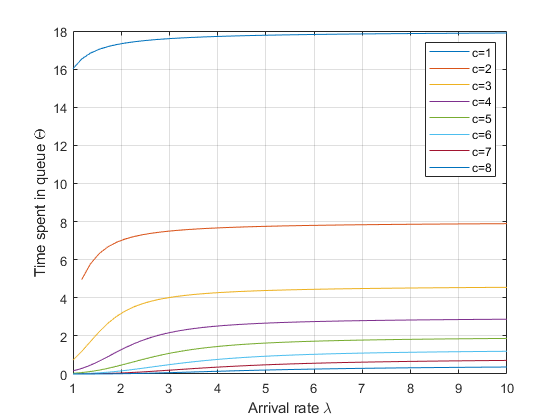

plot(L, Theta, "-");
legend(["c=1", "c=2", "c=3", "c=4", "c=5", "c=6", "c=7", "c=8"], 'Location', 'northeast');
xlabel("Arrival rate \lambda");
ylabel("Time spent in queue \Theta");
grid on;
hold off;

### g. Compute $p_K$

Note that, $p_K$ is the probability of having the system full

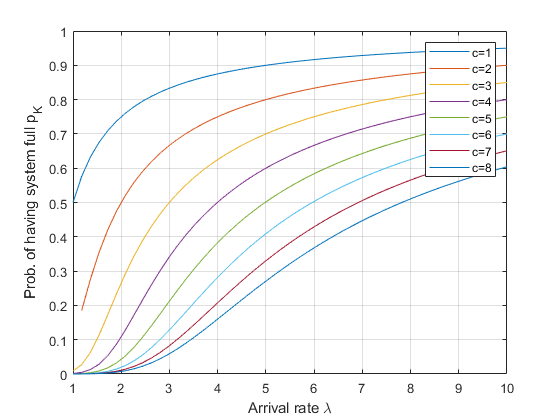

plot(L, Pn(:,:,11), "-");
legend(["c=1", "c=2", "c=3", "c=4", "c=5", "c=6", "c=7", "c=8"], 'Location', 'northeast');
xlabel("Arrival rate \lambda");
ylabel("Prob. of having system full p_K");
grid on;
hold off;